Let's start by creating some data on which to perform inference.

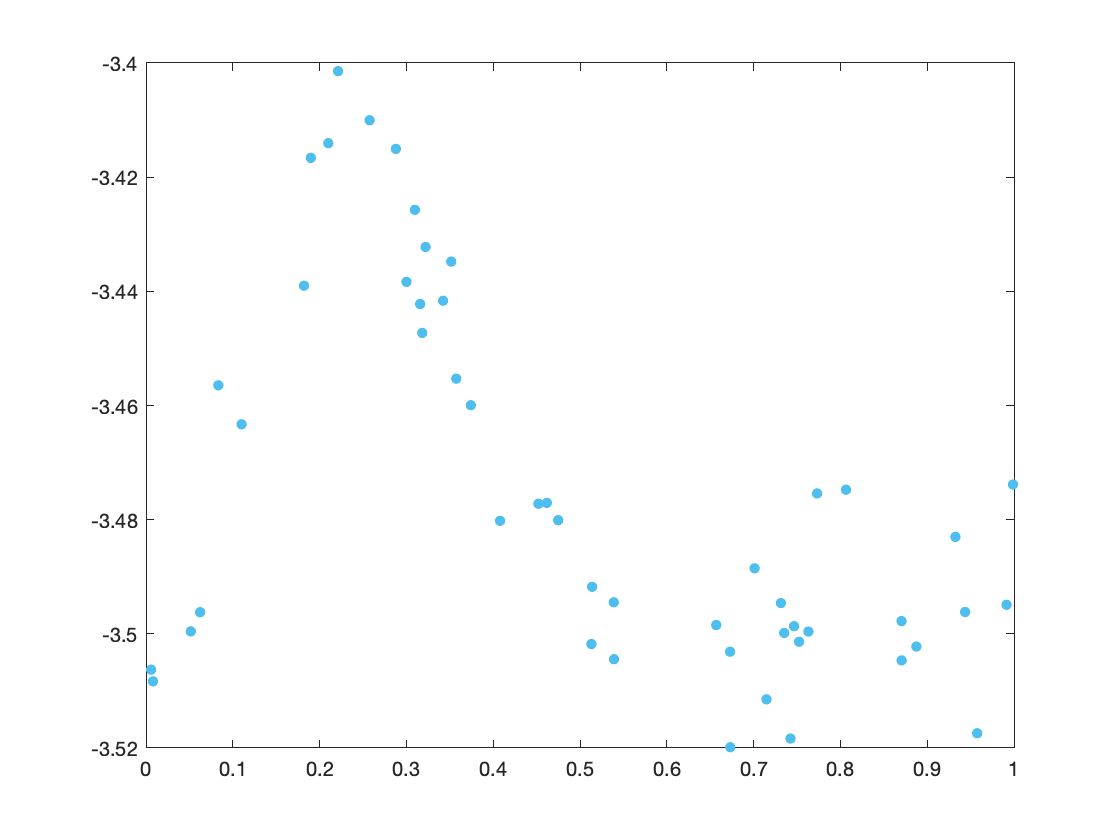

rng(14);
n=50;
x = sort(unifrnd(0,1,[1,n]));
errors = normrnd(0,0.01,[1,n]);
% Data simulation the same as from Perperoglou et al 2019.
y = -3.5+0.2.*x.^11.*10.*(1-x).^6+10.*(10.*x.^3).*(1-x).^10+errors;
plot(x,y,'.r','MarkerEdgeColor',[0.3010 0.7450 0.9330],'MarkerSize',15);

We'll select knots based on the graphic, although more principled methods exist.

knots = [0.0, 0.2, 0.31, 0.5, 0.6, 0.71, 0.87];
bspline_degree = 3;
parameter_dim = length(knots)-(bspline_degree+1)

parameter_dim = 3


indices = 1:(bspline_degree+2);
pp = bspline(knots(indices));
bsplines = pp.coefs

bsplines =    32.2581         0         0         0
 -195.0147   19.3548    3.8710    0.2581
  124.3194  -45.0000    1.0500    0.6585
  -86.2069   25.8621   -2.5862    0.0862



for i=2:(length(knots)-(bspline_degree+2)+1)
    indices = (i):(i+(bspline_degree+2)-1);
    pp = bspline(knots(indices));
    bsplines= vertcat(bsplines, pp.coefs);
end


% Arbitrarily choosing the starting value, with dimension parameter_dim:
q0_temp=[2,3,4];
q0 = q0_temp/integral(@(x)(logspline_density(x,knots,bsplines,q0_temp)),knots(1),knots(length(knots)))

q0 = 	1.0e+-98 *

    0.0869    0.1304    0.1738


nllFunc = @(x) nll_density(x,sd1,sd2,sd3,DataX,DataY,DataZ,shift_vector);
conFunc = @(x) sphereConstraint(x,shift_vector);

% Set parameters (that I don't quite understand)
Nscale = [1000 10000];
nRuns = 1+10;
Nscale = 2000;
runTime = 15; % Time per run in seconds
nTrials = 1;
doPrint = false;

samplers = struct([]);

h = .15;
M = 1;
L = 1;
hmcOpts = struct('intMethod',0,'doPrint',doPrint,'printMod',10);
samplers(end+1).name = sprintf('CHMC (L = %d)',L);
samplers(end).desc = sprintf('M = %g, h = %g',M,h);
samplers(end).func = @(q,N) constrainedHMC(q,nllFunc,conFunc,M,N,L,h,hmcOpts);
samplers(end).N = ceil(Nscale./L);
samplers(end).style = 'b-';

samplerQs = cell(length(samplers),1+nTrials);
samplerStats = cell(length(samplers),1+nTrials);
samplerNLLs = cell(length(samplers),1+nTrials);
samplerTs = zeros(length(samplers),1+nTrials);
for i = 1:numel(samplers)
    fprintf('%s...',samplers(i).name);
    [q1,qs,samplerStats{i,1}] = samplers(i).func(q0,samplers(i).N);
    samplerQs{i,1} = [q0 qs q1];
    samplerTs(i,1) = samplerStats{i,1}.t/samplerStats{i,1}.N;
    samplerNLLs{i,1} = nllFunc(samplerQs{i,1});
    
    currN = ceil(runTime./samplerTs(i,1));
    fprintf('%d samples: ',currN);
    fprintf('\n');
end
mean(samplerStats{1,1}.accepted)
Qs = samplerQs{1,1};
save("HMC_sphereDraws.mat",'Qs');